clc
clear all
close all


#### Load the Agent

load('dqn_phase_agent_single_hyp.mat');


#### Print Hyperparameters

obsInfo = getObservationInfo(agent);
actInfo = getActionInfo(agent);
fprintf('Observation dim: %s\n', mat2str(obsInfo.Dimension));

Observation dim: [4 1]


fprintf('Number of discrete actions (presets): %d\n', numel(actInfo.Elements));

Number of discrete actions (presets): 144


#### Access the Critic

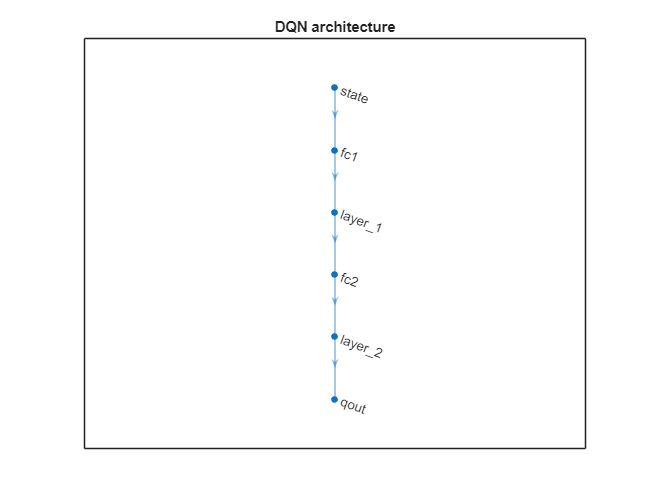

% Get the critic object from the agent
critic = getCritic(agent);

% Access the underlying network (Deep Learning Toolbox object)
% For most versions, this is stored in the 'Model' property
network = getModel(critic);

% (b) Static layer-graph plot
    fig = figure('Name', sprintf('%s - layer graph', "DQN"), ...
                 'Color', 'w', 'Position', [100 100 900 700]);
    plot(network);
    title(sprintf('%s architecture', "DQN"), 'Interpreter', 'none');

#### Display architecture

analyzeNetwork(network)

#### Extract the Coefficients

% Get a table of all weights and biases per layer
coeffTable = network.Learnables;

% Display the first few rows
disp(coeffTable);

    Layer     Parameter          Value      
    ______    _________    _________________

    "fc1"     "Weights"    {119×4   dlarray}
    "fc1"     "Bias"       {119×1   dlarray}
    "fc2"     "Weights"    {119×119 dlarray}
    "fc2"     "Bias"       {119×1   dlarray}
    "qout"    "Weights"    {144×119 dlarray}
    "qout"    "Bias"       {144×1   dlarray}



#### Important Consideration:

- **Weight Orientation:** MATLAB typically stores weights for fully connected layers in the format **[OutputChannels x InputChannels]**. If you are moving these to Python (PyTorch/TensorFlow), you may need to transpose them.